clear all
biomass_0m;


for cycle=1:11
    radius(cycle)=0.0;
    
    varname=genvarname(['biomass_' int2str((cycle-1)*1000) '_0']);
    biomass_field=eval(varname);
    %biomass_field(:,:)=0.0;
    
    radial_biomass(1:176)=0.0;
    for x=1:352
        for y=1:352
            biomass=biomass_field(x,y);
            Rcurrent=sqrt((x-176)^2+(y-176)^2);
            for r=1:176
                if Rcurrent>r-1 && Rcurrent <=r
                    radial_biomass(r)=radial_biomass(r)+biomass;
                end
            end
        end
    end
    for r=1:175
        if radial_biomass(r)>radial_biomass(r+1)
            radius(cycle)=r*0.01;
        end
    end
end

f1=plot(0.05*[0:1000:10000]/24,radius(1:11),LineWidth=2,Color='magenta')

f1 =   Line with properties:

              Color: [1 0 1]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 2.0833 4.1667 6.2500 8.3333 10.4167 12.5000 14.5833 16.6667 18.7500 20.8333]
              YData: [0.2400 0.5500 0.7400 0.8200 0.8400 0.8500 0.8500 0.8500 0.8500 0.8500 0.8500]

  Show all properties


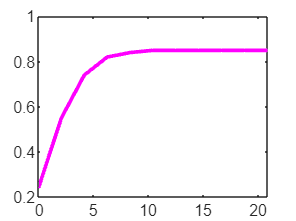

hold on

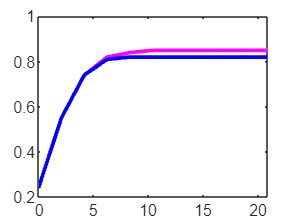

biomass_16m;
for cycle=1:11
    radius(cycle)=0.0;
    
    varname=genvarname(['biomass_' int2str((cycle-1)*1000) '_0']);
    biomass_field=eval(varname);
    %biomass_field(:,:)=0.0;
    
    radial_biomass(1:176)=0.0;
    for x=1:352
        for y=1:352
            biomass=biomass_field(x,y);
            Rcurrent=sqrt((x-176)^2+(y-176)^2);
            for r=1:176
                if Rcurrent>r-1 && Rcurrent <=r
                    radial_biomass(r)=radial_biomass(r)+biomass;
                end
            end
        end
    end
    for r=1:175
        if radial_biomass(r)>radial_biomass(r+1)
            radius(cycle)=r*0.01;
        end
    end
end

plot(0.05*[0:1000:10000]/24,radius(1:11),LineWidth=2,Color='blue')

%hold on

biomass_M8_small;
for cycle=1:11
    radius(cycle)=0.0;
    
    varname=genvarname(['biomass_' int2str((cycle-1)*500) '_0']);
    biomass_field=eval(varname);
    %biomass_field(:,:)=0.0;
    
    radial_biomass(1:176)=0.0;
    for x=1:352
        for y=1:352
            biomass=biomass_field(x,y);
            Rcurrent=sqrt((x-176)^2+(y-176)^2);
            for r=1:176
                if Rcurrent>r-1 && Rcurrent <=r
                    radial_biomass(r)=radial_biomass(r)+biomass;
                end
            end
        end
    end
    for r=1:175
        if radial_biomass(r)>radial_biomass(r+1)
            radius(cycle)=r*0.01;
        end
    end
end

plot(0.05*[0:500:5000]/24,radius(1:11),LineWidth=2,Color='green')
hold on

biomass_M16_small;
for cycle=1:11
    radius(cycle)=0.0;
    
    varname=genvarname(['biomass_' int2str((cycle-1)*500) '_0']);
    biomass_field=eval(varname);
    %biomass_field(:,:)=0.0;
    
    radial_biomass(1:176)=0.0;
    for x=1:352
        for y=1:352
            biomass=biomass_field(x,y);
            Rcurrent=sqrt((x-176)^2+(y-176)^2);
            for r=1:176
                if Rcurrent>r-1 && Rcurrent <=r
                    radial_biomass(r)=radial_biomass(r)+biomass;
                end
            end
        end
    end
    for r=1:175
        if radial_biomass(r)>radial_biomass(r+1)
            radius(cycle)=r*0.01;
        end
    end
end

plot(0.05*[0:500:5000]/24,radius(1:11),LineWidth=2,Color='red')
hold on

xlim([0,12])
ylim([0,1.2])
xlabel('Time [days]')
ylabel('Colony radius [cm]')
legend('ATP Maintenance Req. = 0 [mmol/g·h]','ATP Maintenance Req. = 4 [mmol/g·h]','ATP Maintenance Req. = 8 [mmol/g·h]','ATP Maintenance Req. = 16 [mmol/g·h]','Location','southeast',FontSize=12)
ax=gca;
ax.FontSize=18



exportgraphics(gcf,'radius.png','Resolution', 300)
